# Lab - Systems of equations 1

**Topics: **Cramer's rule, left divide, LU factorization

## Cramer's rule and left divide

clear, clc, format compact

An electrical engineer supervises production of three types of electrical parts.  The amounts of material (in g/component) needed to produce the parts are:

             METAL     PLASTIC       RUBBER

Part 1 -        15              0.3                    1

Part 2 -        17              0.4                    1.2

Part 3 -        19             0.55                   1.5

3.89, 0.095, and 0.282 kg of metal, plastic and rubber are available each day. 

A = [15 17 19; .3 .4 .55; 1 1.2 1.5]

A =    15.0000   17.0000   19.0000
    0.3000    0.4000    0.5500
    1.0000    1.2000    1.5000


b = [3.89;.095;.282]

b =     3.8900
    0.0950
    0.2820


b = b*1000;


### How many units of part 2 can be produced?  

c = A\b;

A2 = A;
A2(:,2) = b;
part2 = det(A2)/det(A)

part2 = 60.0000

fprintf('%d units of part 2 can be produced\n', floor(c(2)))

59 units of part 2 can be produced


### How many total parts can be produced?


fprintf('%d parts can be produced\n', floor(sum(c)))

230 parts can be produced


## LU factorization - chloride concentrations

clear, clc, format compact

The Lower Colorado River consists of 4 reservoirs.  Mass balances can be written for each reservoir, and the following sets of simultaneous equations results:


$$\left\lbrack \begin{array}{cccc}
13\ldotp 422 & 0 & 0 & 0\\
-13\ldotp 422 & 12\ldotp 252 & 0 & 0\\
0 & -12\ldotp 252 & 12\ldotp 377 & 0\\
0 & 0 & -12\ldotp 377 & 11\ldotp 797
\end{array}\right\rbrack \left\lbrace \begin{array}{c}
c_1 \\
c_2 \\
c_3 \\
c_4 
\end{array}\right\rbrace =\left\lbrace \begin{array}{c}
750\ldotp 5\\
300\\
102\\
30
\end{array}\right\rbrace$$
   

The RHS vector consists of the loading of chloride to each of the lakes and the unknowns are the resulting chloride concentrations for Lakes Powell, Mead, Mohave, and Havasu respectively.  **Determine the chloride concentration for each lake.**    

A = [13.422  0        0      0;
    -13.422  12.252   0      0;
     0       -12.252  12.377 0;
     0 0     -12.377        11.797]; % coefficient matrix

b1 = [750.5 300 102 30]'; % chloride loading

### Factorization 

L = eye(4);% Matrix of factors
U = A;% new matrix to manipulate so we preserve A

factor21 = U(2,1)/U(1,1);
U(2,:) = U(2,:)-factor21*U(1,:);
L(2,1) = factor21;
factor32 = U(3,2)/U(2,2);
U(3,:) = U(3,:) - factor32*U(2,:);
L(3,2) = factor32;
factor43 = U(4,3)/U(3,3);
U(4,:) = U(4,:) - factor43*U(3,:)

U =    13.4220         0         0         0
         0   12.2520         0         0
         0         0   12.3770         0
         0         0         0   11.7970


L(4,3) = factor43

L =      1     0     0     0
    -1     1     0     0
     0    -1     1     0
     0     0    -1     1



sum(sum(L*U-A))% check 1  L*U = A

ans = 0

% if L*U = A, then the difference between L*U - A should be a matrix of all
% zeros.  add up the columns, then add up the resulting row vector and
% should get 0
% check1 = sum(sum(?*? - ?)) % should be zero 

### Forward substitution

 $\textrm{Ld}=b\;$perform manipulations on b to get d

%d = L\b1

d(1) = b1(1);
d(2,1) = b1(2)-L(2,1)*d(1);
d(3,1) = b1(3) - L(3,1)*d(1) - L(3,2)*d(2);
d(4,1) = b1(4) - L(4,1)*d(1) - L(4,2)*d(2) - L(4,3)*d(3);

% checkpoint #2 
% if L*d = b, then the difference between L*d - b should be a vector of all
% zeros.  sum the vector, it should be 0
% check2 = sum(?*?-?) % should be zero
sum(L*d-b1)

ans = 0

### Back subsitution  

$\textrm{Ux}=d$ Solve for the unknowns

x_LU1 = zeros(4,1);

x_LU1(4) = d(4)/U(4,4);
x_LU1(3) = (d(3) - U(3,4)*x_LU1(4))/U(3,3);
x_LU1(2) = (d(2) - U(2,3)*x_LU1(3) - U(2,4)*x_LU1(4))/U(3,3);
x_LU1(1) = (d(1) - U(1,2)*x_LU1(2) - U(1,3)*x_LU1(3) - U(1,4)*x_LU1(4))/U(3,3);

sum(A*x_LU1-b1)

ans = 0


% Checkpoint 3 A*x = b
% if A*x = b, then the difference between A*x - b should be a vector of all
% zeros.  sum the vector, it should be 0
% Check3 = sum(?*? - ?) % should be zero 

### Displaying the results

lakes = ["Powell" "Mead" "Mohave" "Havasu"];
fprintf(['Chloride concentrations by lake [in mg/L]:\n' ...
    '%6s %6s %6s %6s\n' ...
     '------ ------ ------ ------\n' ...
     '%6.2f %6.2f %6.2f %6.2f\n'], lakes, x_LU1)

Chloride concentrations by lake [in mg/L]:
Powell   Mead Mohave Havasu
------ ------ ------ ------
 60.64  84.88 1152.50 100.24


### Changing the chloride load

Chloride is a relatively benign ion at low concentrations but begins to have ecological impacts as concentrations rise into the 100s of mg/L.

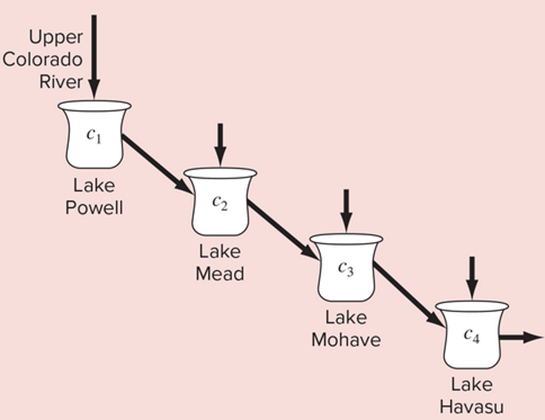

**If we change the loading of chloride in Lake Mead to 5, will all the chloride concentrations in the lakes be below 100 mg/L?**

% Update b vector
b2 = b1;
b2(2) = 5;
% Skip the elimination step!!!
d2 = L\b2;
% Forward substitution
x_LU2  = U\d2;
% Back substitution

% Checkpoint 4 A*new_x = b
sum(A*x_LU2-b2) % should be zero

ans = 0

### Updated results

if max(0) < 100
    disp('The chloride concentrations in all lakes WILL be below 100 mg/L\n')
else
    disp('The chloride concentrations in all lakes WILL NOT be below 100 mg/L\n')
end

The chloride concentrations in all lakes WILL be below 100 mg/L\n



fprintf(['Updated chloride concentrations by lake [in mg/L]:\n' ...
    '%6s %6s %6s %6s \n' ...
     '------ ------ ------ ------\n' ...
     '%6.2f %6.2f %6.2f %6.2f\n'], lakes, x_LU2)

Updated chloride concentrations by lake [in mg/L]:
Powell   Mead Mohave Havasu 
------ ------ ------ ------
 55.92  61.66  69.28  75.23
